inflated_polyshapes =   polyshape - 属性:

      Vertices: [51×2 double]
    NumRegions: 1
      NumHoles: 1


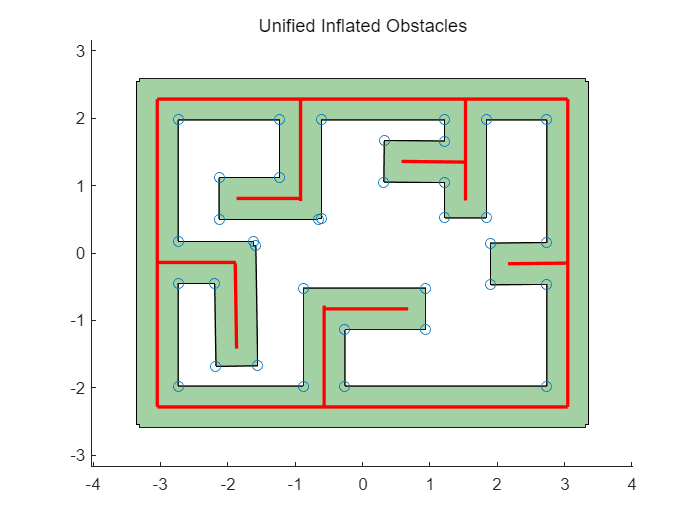

load("practicemap2025update.mat")
% plot inflated wall and vertices
[concex_vertices_list, union_obstacle] = createInflatedMap(map, 0.1,0.16, 0.1);

[V,E] = createRoadMap2(concex_vertices_list, union_obstacle, waypoints);

函数或变量 'wall_vertices_list' 无法识别。


% plotMap("hw6b.txt",[0,0,100,100]);

% graph = {V,E};
% initial = [80,95];
% goal = [10,50];
% [shortestPath, V, E] = findPath("hw6b.txt", graph, initial, goal);
% 
for i=1:size(E,1)
    edge = E(i,:);
    h_edge = plotEdge([edge(1),edge(2)], [edge(3),edge(4)]);
end
% h_initial = scatter(initial(1), initial(2),200, 'o','Color','orange', "DisplayName","Initial Point");
% h_end = scatter(goal(1), goal(2),200,'go',"DisplayName","Goal Point");
% h_path = plot(shortestPath(:,1), shortestPath(:,2),'b--','LineWidth', 2,"DisplayName","Shortest Path")
title("Shortest Path on Roadmap");
xlabel("X");
ylabel("Y");
% legend_handles = [h_initial, h_end, h_path];
% legend(legend_handles);
